# Reinforcement Learning Lab #1 - Solution

## Introduction

- Assume a neural network composed of three layers of neurons: input layer, hidden layer and output layer. We wish to train this network so when it is presented with a specific input it will have a certain output.

- For this lab we are going to work with the [MNIST database of handwritten digits](http://yann.lecun.com/exdb/mnist) and train our network to recognise handwritten 0-9 digits. The MNIST database contains 60000 images which can used to train the network and 10000 more images for testing purposes. Each image is an matrix representing a digit.

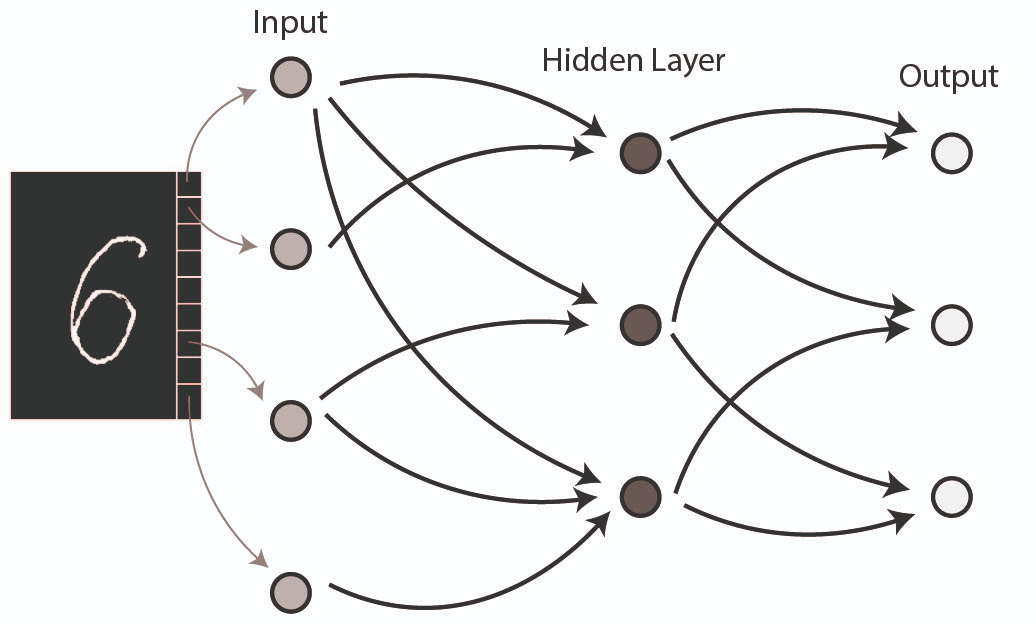

## The neural network

Network initialisation

- Generate a set of weights between the input and the hidden layer. The input layer should have 784 neurons, one for each pixel of the image.

- Generate a set of weights between the hidden and the output layer. The output layer should have 10 neurons, one for each digit.

- Generate two sets of bias, one for the hidden layer and one for the output layer. Bias is set to 0 to start with

**Feedforward**

- Feed an image $$\vec{x(\mu)}$ $ to the network.

- Compute the input to each of the neurons of the hidden layer, $ $h^{(1)}_i = \sum_{j=1}^{784}w^{(1)}_{ij} x^{(0)}_j + b^{(1)}_i$$ and their outputs with the use of the [sigmoid function](http://mathworld.wolfram.com/SigmoidFunction.html)$$x^{(1)}_i = f(h^{(1)}_i) = \frac{1}{(1+e^{-h^{(1)}_i})}$$

-  Repeat for the output layer, $$h^{(2)}_i = \sum_{j=1}^{784}w^{(2)}_{ij} x^{(1)}_j + b^{(2)}_i$$ and their outputs, $$x^{(2)}_i = f(h^{(2)}_i)$$ 

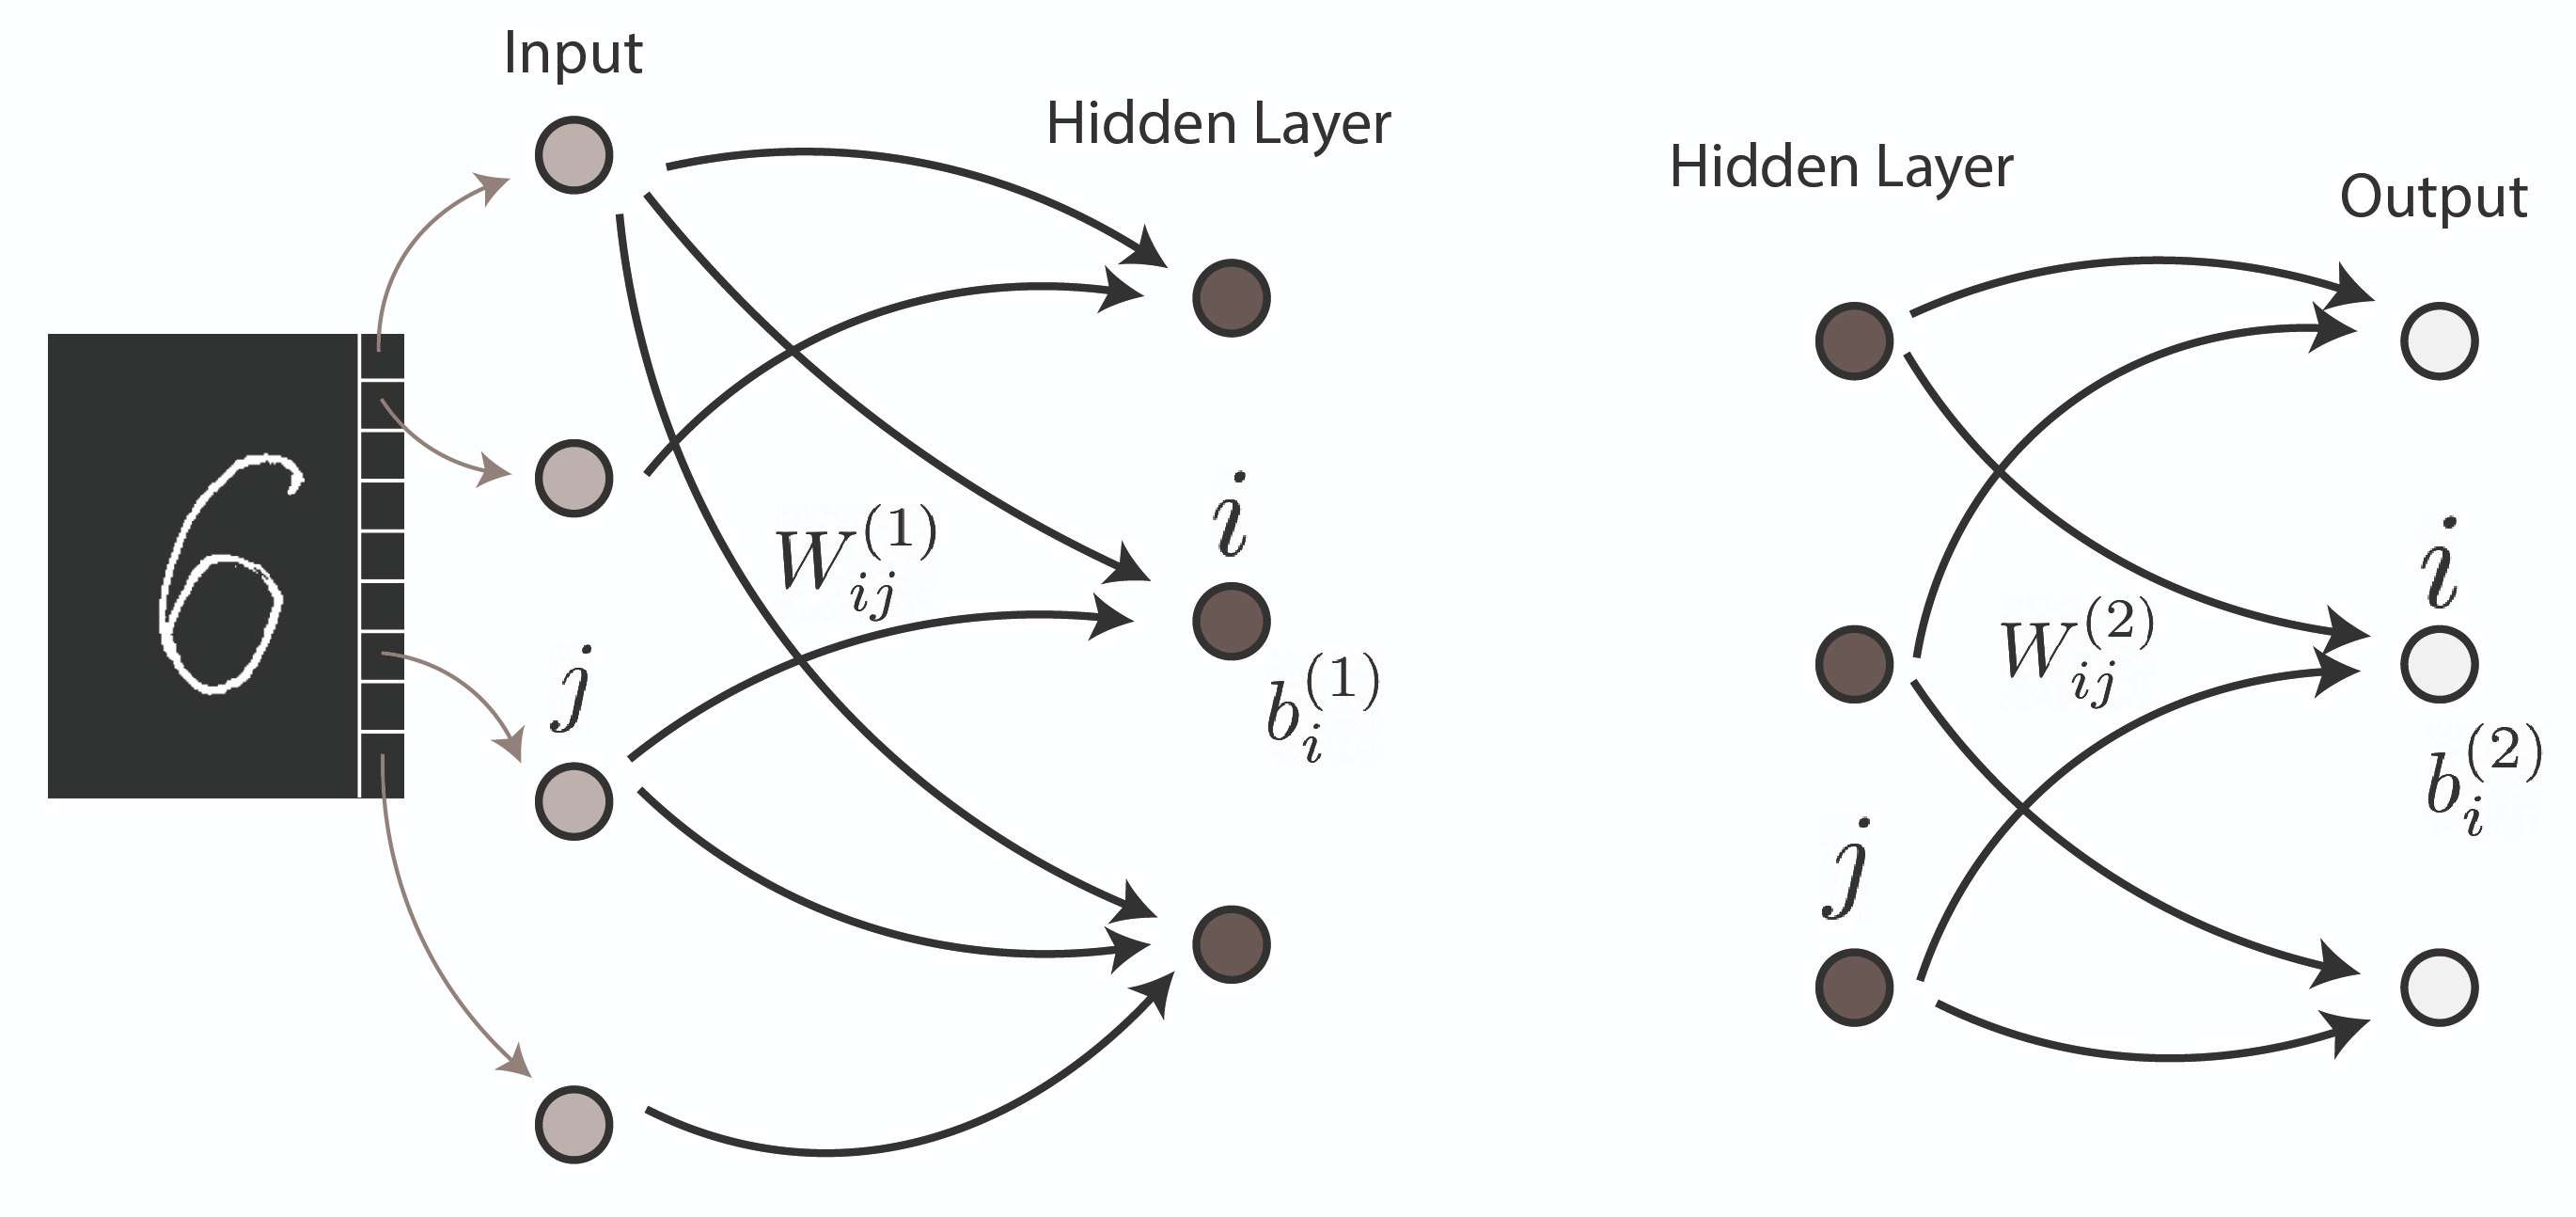

**Error**

- Calculate the error in the output of the neural network. If the input is an image of a zero digit it is expected that the first neuron of the input layer to be fully active, i.e has an output of 1, while the other neurons have outputs of 0. Thus the target output would be $$t = [1,0,0,\dots,0]^T$$ and, given that the output of the neural network is some 𝑜𝑢𝑡𝑝𝑢𝑡, the error is given by the formula


$$$$E(\mu) = \sum_{i=1}^{n}\frac{1}{2}(t_i(\mu)-x^{(2)}_i(\mu))^2,$$$$


            where 𝑛 is the number of neurons in the output layer of the network and 𝜇 is sample index. The total error per sample is then given by


$$$$E/N = \sum_{\mu=1}^N \sum_{i=1}^{n}\frac{1}{2N}(t_i(\mu)-x^{(2)}_i(\mu))^2.$$$$


### **Backpropagation**

Here we will consider explicitly the logistic sigmoid activation function so we can use the result that the derivative of the logistic sigmoid is


$$$$ f'(h) = \frac{\partial f(h) }{\partial h } = f(h)(1-f(h)) $$$$


directly in the update rules.

1.Apply the delta rule between the output and the hidden layers. For the weight $$w_{ij}$$ we have


$$$$\frac{\partial E}{\partial w_{\textrm{ij}} }=\frac{\partial E}{\partial x^{(2)}_i }\;\frac{\partial x^{(2)}_i }{\partial h^{(2)}_i } \; \frac{\partial h^{(2)}_i }{\partial w_{\textrm{ij}} } \; =-\left( t_i -x^{(2)}_i \right)\; x^{(2)}_i \;\left(1-x^{(2)}_i \right) \; x^{(1)}_j,$$ $$


and we can define $$\delta^{(2)}_i = \left(t_i - x^{(2)}_i \right)x^{(2)}_i \;\left(1-x^{(2)}_i \right) $$.

 2. Update the weights between the hidden and the output layers.For the weight $ $w_{ij}$$ we have the update after a single input 


$$$${\Delta w}_{\textrm{ij}} = \eta \delta^{(2)}_i x^{(1)}_j.$$$$


3. Repeat steps 1 and 2 between the hidden and the input layes and update the weights between them. Here for the weight $$w_{ij}$$ we have 


$$$\frac{\partial E}{\partial w_{\textrm{ij}} }=\frac{\partial E}{\partial x^{(1)}_j }\;\frac{\partial x^{(1)}_j }{\partial h^{(1)}_j }\;\frac{\partial h^{(1)}_j }{\partial w_{\textrm{ij}} }=x^{(0)}_j x^{(1)}_i \;\left(1-x^{(1)}_i \right) \sum_k \left(w^{(2)}_{\textrm{ki}} \delta^{(2)}_k \right)$$$


 where the terms $$w_{\textrm{ij}}^{\left(2\right)}, \delta_j^{\left(2\right)}$$ are the weights and the delta function of the previous layer. So now we can defined the backpropagated local gradient for the hidden layer as 


$$$ \delta_i^{(1)} = x^{(1)}_i \;\left(1-x^{(1)}_i \right) \sum_j \delta^{(2)}_j w^{(2)}_{ji}. $$$


4. Update the weights between the hidden and the input layers. For the weight $$w_{ij}$$we have


$$$${\Delta w}_{\textrm{ij}} =\eta \delta^{(1)}_i x^{(0)}_j.$$$$


## Exercises

The code provided first loads the MNIST database and generates a neural network using the parameters provided. Then it trains the network and tests it using the testing set of the MNIST database.

- Test the network using the test dataset, then compute and comment on it's accuracy.

- The weights are generating from a uniformly distribution in the interval (0,1) and are then normalized using the sum equals to 1 normalization, i.e the summation of the inputs should be equal to 1. Why is this normalization important? Another initialisation method is the [Xavier initialization](http://www.jmlr.org/proceedings/papers/v9/glorot10a/glorot10a.pdf?hc_location=ufi), which is more commonly used in deep neural networks of more than one hidden layer. In this initialisation the weights are initialised using normally distributed random numbers which are then scaled by sqrt(1/n_cols). Change your initialisation to this and comment on how this changes the training.

- The weights are updated through mini-batches. Change the mini-batch size and see the effect that this has on performance and computational speed. What are the limits in defining a mini-batch size?

- A bias is included in the calculation of the activation but is set to zero and is not trained. Derive the learning rule and code the training of the bias alongside the weights. It may help to think of the bias as an extra weight where the input value is fixed to 1.

- Upgrade the network by adding one more hidden layer, derive the appropriate formulas for the feedforward and the backpropagation and program them.

- Try to use ten classes and to optimise the network hyperparameters.

% Load the MNIST dataset:
% The MNIST dataset contains 60,000 training samples.
% To start with we will limit this to 5 classes (the first 5 digits in the dataset) to simplify development
mnist = load('MNIST.mat');

% Read the train set
x_train = mnist.x_train;
% Read the train labels
trainlabels = mnist.trainlabels;
 
% Read the test set
x_test = mnist.x_test;
% Read the test labels
testlabels = mnist.testlabels;

% We select the data for the classes that we want to classify
% 
N_class=10;
% 
Index_tr=[];
Index_te=[];
 
for i = 0:N_class-1
    % Find the indexes of the training set corresponding to class i
    ind_tr = find(trainlabels==i);
    % Find the indexes of the test set corresponding to class i
    ind_te = find(testlabels==i);
    % Append the training indexes in a list
    Index_tr = [Index_tr;ind_tr];
    % Append the testing indexes in a list
    Index_te = [Index_te;ind_te];
end

% Create a training set and a test set with data belonging to the classes considered only
x_train = x_train(Index_tr,:);
x_test =  x_test(Index_te,:);

% Compute the size of the train and test datasets
N_tr = numel(Index_tr);
N_te = numel(Index_te);

% Create one-hot encoding labels for train and test datasets
y_train = zeros(N_tr,N_class);
y_test =  zeros(N_te,N_class);

for i=1:N_tr 
     y_train(i,trainlabels(Index_tr(i))+1) = 1;
end 

for i=1:N_te 
     y_test(i,testlabels(Index_te(i))+1) = 1;
end  
[n_samples, img_size] = size(x_train)

n_samples = 60000

img_size = 784

## Example view of image 

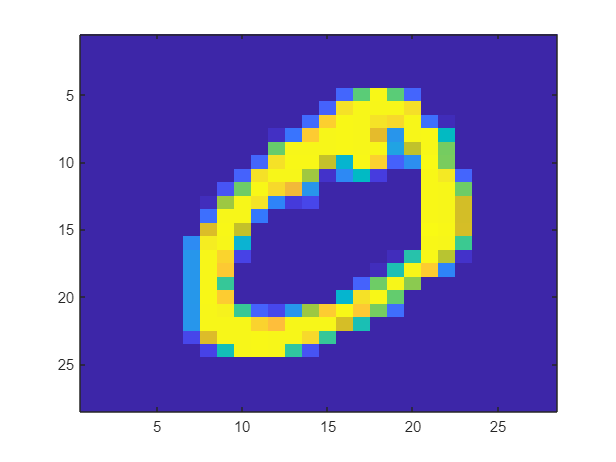

example_image = reshape(x_train(1,:),28,28);
imagesc(example_image)

## Set Hyperparameters

% The number of epochs is a hyperparameter that defines the number times that the learning algorithm 
% will work through the entire training dataset.

% The batch size is a hyperparameter that defines the number of samples to work through before 
% updating the internal model parameters. 

% ref: https://machinelearningmastery.com/difference-between-a-batch-and-an-epoch/

n_epoch = 10;
batch_size = 20;
n_batches = floor(n_samples/batch_size);

% define the size of each of the layers in the network
n_input_layer  = img_size;
n_hidden_layer = 100;
n_output_layer = N_class;

% Add another hidden layer
n_hidden_layer2 = 100; % number of neurons of the hidden layer. 0 deletes this layer

% eta is the learning rate
eta = 0.5;

## Initialize a simple network

% For W1 and W2 columns are the input and the rows are the output.
% W1: Number of columns (input) needs to be equal to the number of features 
%     of the  MNIST digits, thus p. Number of rows (output) should be equal 
%     to the number of neurons of the hidden layer thus n_hidden_layer.
% W2: Number of columns (input) needs to be equal to the number of neurons 
%     of the hidden layer. Number of rows (output) should be equal to the 
%     number of digits we wish to find (classification).

Xavier_init = false;

if Xavier_init
    W1 = randn(n_hidden_layer, n_input_layer) .* sqrt(1 / n_input_layer);
    if n_hidden_layer2 > 0
        W2 = randn(n_hidden_layer2, n_hidden_layer) * sqrt(1 / n_hidden_layer)
        W3 = randn(n_output_layer, n_hidden_layer2) * sqrt(1 / n_hidden_layer2)
    else
        W2 = randn(n_output_layer, n_hidden_layer) * sqrt(1 / n_hidden_layer)
    end
else
    W1 = rand(n_hidden_layer, n_input_layer);
    W2 = rand(n_output_layer, n_hidden_layer);

    % The following normalises the random weights so that the sum of each row =1
    W1 = W1 ./ sum(W1,2);
    W2 = W2 ./ sum(W2,2);

   if n_hidden_layer2 > 0
       W3 = rand(n_output_layer,n_hidden_layer2);
       W3 = W3 ./sum(W3,2);

       W2 = rand(n_hidden_layer2,n_hidden_layer);
       W2 = W2 ./ sum(W2,2);
    end
end

## Initialize the biases

bias_W1 = zeros(n_hidden_layer,1);
bias_W2 = zeros(n_output_layer,1);

if n_hidden_layer2 > 0    
    bias_W3 = zeros(n_output_layer,1);
    bias_W2 = zeros(n_hidden_layer2,1);
end
% Keep track of the network inputs and average error per epoch
errors = zeros(n_epoch,1);

## Train the network


for i = 1:n_epoch
    % We will shuffle the order of the samples each epoch
    shuffled_idxs = randperm(n_samples);

    for batch = 1:n_batches
        % Initialise the gradients for each batch
        dW1 =  zeros(size(W1));
        dW2 =  zeros(size(W2));

        dbias_W1 = zeros(size(bias_W1));
        dbias_W2 = zeros(size(bias_W2));

        if n_hidden_layer2 > 0
            dW3 = zeros(size(W3));
            dbias_W3 = zeros(size(bias_W3));
        end

        % Loop over all the samples in the batch
        for j = 1: batch_size
            % Input (random element from the dataset)
            idx = shuffled_idxs((batch-1)*(batch_size-1) + j);
            x0 = x_train(idx,:)';

            % Form the desired output, the correct neuron should have 1 the rest 0
            desired_output = y_train(idx,:)';

            % Neural activation: input layer -> hidden layer
            h1 = W1 * x0 + bias_W1;

            % Apply the sigmoid function
            x1 = 1./(1 + exp(-h1));

            % Neural activation: hidden layer -> output layer
            h2 = W2 * x1 + bias_W2;

            % Apply the sigmoid function
            x2 = 1./(1+ exp(-h2));

            if n_hidden_layer2 > 0
                % Neural activation: hidden layer 1 -> hidden layer 2
                h3 = W3*x2 + bias_W3;

                % Apply the sigmoid function
                x3 = 1 ./ (1 + exp(-h3));

                % Compute the error signal
                e_n = desired_output - x3;

                % Backpropagation: output layer -> hidden layer 2
                delta3 = x3.*(1-x3) .* e_n;

                dW3 = dW3 + kron(delta3,x2');
                dbias_W3 = dbias_W3+ delta3;

                % Backpropagation: hidden layer -> input layer
                delta2 = x2.*(1-x2) .* (W3'*delta3);
            else
                % Compute the error signal
                e_n = desired_output - x2;

                % Backpropagation: output layer -> hidden layer
                delta2 = x2.*(1-x2) .* e_n;
            end

            dW2 = dW2+ kron(delta2, x1');
            dbias_W2 = dbias_W2 + delta2;

            % Backpropagation: hidden layer -> input layer
            delta1 = x1.*(1-x1) .* (W2'* delta2);
            dW1 = dW1 +  kron(delta1,x0');
            dbias_W1 = dbias_W1 + delta1;

            % Store the error per epoch
            errors(i) = errors(i) + 0.5 * sum(e_n.*e_n)./n_samples;
        end

        %After each batch update the weights using accumulated gradients
        W2 = W2 + eta.*dW2./batch_size;
        W1 = W1 + eta.*dW1./batch_size;

        bias_W1 =  bias_W1 + eta.*dbias_W1./batch_size;
        bias_W2 = bias_W2 + eta.*dbias_W2./batch_size;

        if n_hidden_layer2 > 0
            W3 = W3 + eta.*dW3./batch_size;
            bias_W3 = bias_W3 + eta.*dbias_W3./batch_size;
        end

    end
    fprintf( "Epoch %d: error = %f\n",i,errors(i));
end

Epoch 1: error = 0.451781
Epoch 2: error = 0.450768
Epoch 3: error = 0.450458
Epoch 4: error = 0.449323
Epoch 5: error = 0.379716
Epoch 6: error = 0.349414
Epoch 7: error = 0.200999
Epoch 8: error = 0.093945
Epoch 9: error = 0.071435
Epoch 10: error = 0.059924


## Plot the performance

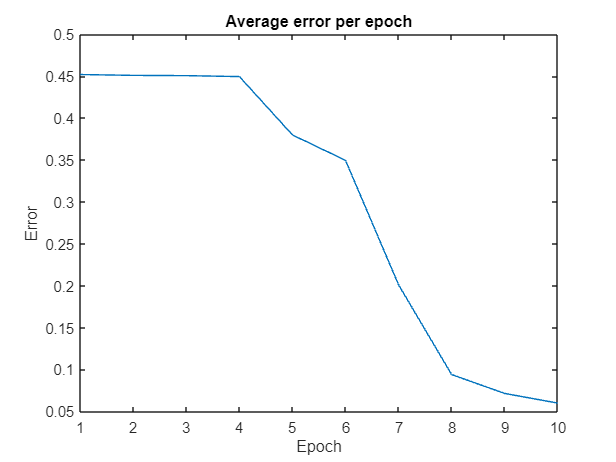

plot(errors)
xlabel("Epoch")
ylabel("Error")
title("Average error per epoch")

##   Use the test set to compute the network's accuracy

n = height(x_test);

p_ra = 0;
correct_value = zeros(n,1);
predicted_value = zeros(n,1);

for i =1:n
    x0 = x_test(i,:)';
    y = y_test(i,:)';

    [~,correct_value(i)] = max(y);

    h1 = W1*x0 + bias_W1;
    x1 = 1 ./ (1 + exp(-h1));

    h2 = W2* x1 + bias_W2;
    x2 = 1 ./ (1 + exp(-h2));

    if n_hidden_layer2 > 0
        h3 = W3* x2 + bias_W3;
        x3 = 1 ./ (1 + exp(-h3));
        [~,predicted_value(i)] = max(x3);
    else
        [~,predicted_value(i)] = max(x2);
    end

    if predicted_value(i) == correct_value(i)
        p_ra = (p_ra + 1);
    end
end
accuracy = 100*p_ra/n; 
fprintf("Accuracy (percentage of correct classifications) = %.2f\n", accuracy);

Accuracy (percentage of correct classifications) = 93.05
